% Clear workspace, load your data, and prepare the environment
cd('C:\Users\hanib\Desktop\validationSetup\Validation Version 2\');
load("allCoeff.mat");
load("experiment.mat");  % Load the experiment data

% Compare different ID cases based on their IDs (1 to 13150)
ids = [1, 19, 37];  % Change or add/remove IDs here for comparison
num_ids = length(ids);  % Get the number of IDs to compare
cycles_to_sim = 2000;  % Number of cycles to simulate
t_step = 0.08;  % Time step for the simulation
T_air = 70;     % Air temperature

% Surface areas
S_aria = 7.932558e-02;
S_settle = 1.011951e-02;
S_counter = 1.504496e-02;

% Physical constants
C_mold = 1 / (2278.4 * 7300.0 * 2.196412e-03); % Mold heat capacity
C_gob = 1 / (1460.0 * 2350.0 * 9.288814e-05); % Gob heat capacity

% Initialize arrays to hold the temperatures for each cycle and each ID
gob_ts_all = cell(num_ids, 1);
mold_ts_all = cell(num_ids, 1);

% Loop through each ID to run the simulation
for idx = 1:num_ids
    id = ids(idx);
    
    % Determine coefficient set (1 to 75) for the current ID
    coeff_id = ceil(id / 18);

    disp("========================================");
    disp("The ID is "+id);
    disp(" and its related ID for coefficients is "+coeff_id);
    
    % Extract coefficients for the current coefficient set
    a1 = fliplr(table2array(allCoeff(coeff_id, 1:4)));
    a2 = fliplr(table2array(allCoeff(coeff_id, 5:8)));
    b1 = fliplr(table2array(allCoeff(coeff_id, 9:12)));
    b2 = fliplr(table2array(allCoeff(coeff_id, 13:16)));
    ks = fliplr(table2array(allCoeff(coeff_id, 17:20)));
    kc = fliplr(table2array(allCoeff(coeff_id, 21:24)));

    % Display the coefficients
    disp("Coefficients for ID: "+id);
    disp("a1 = "), disp(a1);
    disp("a2 = "), disp(a2);
    disp("b1 = "), disp(b1);
    disp("b2 = "), disp(b2);
    disp("ks = "), disp(ks);
    disp("kc = "), disp(kc);

    % Extract experiment parameters for the current ID
    t_settle_start = experiment.timingssettlestart(id);
    t_settle = experiment.timingssettleend(id) - t_settle_start;
    t_counter_start = experiment.timingscounterstart(id);
    t_counter = experiment.timingscounterend(id) - t_counter_start;
    t_cooling_start = experiment.timingscoolingstart(id);
    t_cooling = experiment.timingscoolingend(id) - t_cooling_start;
    t_cycle = experiment.cycle_duration(id);
    T_g = experiment.gobstart(id);  % Initial gob temperature
    T_m = experiment.moldstart(id);  % Initial mold temperature

    disp("The Parameters for the ID= "+id+ " are as follows:");
    disp("Settle start: " + t_settle_start + ", Settle duration: " + t_settle);
    disp("Counter start: " + t_counter_start + ", Counter duration: " + t_counter);
    disp("Cooling start: " + t_cooling_start + ", Cooling duration: " + t_cooling);
    disp("Gob start temperature: " + T_g);
    disp("Mold start temperature: " + T_m);

    gob_ts = [];
    mold_ts = [];
    
    % Main Loop for Simulation (2000 cycles)
    for i = 1:cycles_to_sim
        [gob_cycle, mold_cycle, ~, ~] = simulate_cycle(T_g, T_m, ...
                           t_settle_start, t_settle, ...
                           t_counter_start, t_counter, ...
                           t_cooling_start, t_cooling, ...
                           t_cycle, t_step, a1, a2, b1, b2, ks, kc, ...
                           S_settle, S_counter, S_aria, C_mold, C_gob, T_air);

        gob_ts = [gob_ts, gob_cycle];
        mold_ts = [mold_ts, mold_cycle];

        % Update the initial mold temperature for the next cycle
        T_m = mold_ts(end);
    end

    % Store the results for the current ID
    gob_ts_all{idx} = gob_ts;
    mold_ts_all{idx} = mold_ts;
end

The ID is 1


 and its related ID for coefficients is 1


Coefficients for ID: 1


a1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0105    2.3547



a2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0117   -2.5594



b1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0200    4.1299



b2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0185   -3.7700



ks = 
   1.0e+06 *

   -0.0000    0.0001   -0.0315    4.0735



kc = 
   1.0e+05 *

   -0.0000    0.0009   -0.1782    7.1833



The Parameters for the ID= 1 are as follows:


Settle start: 0, Settle duration: 3.12


Counter start: 3.12, Counter duration: 1.6


Cooling start: 0.64, Cooling duration: 5.36


Gob start temperature: 1100


Mold start temperature: 404.0019


The ID is 19


 and its related ID for coefficients is 2


Coefficients for ID: 19


a1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0104    2.3180



a2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0116   -2.5259



b1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0200    4.0874



b2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0185   -3.7332



ks = 
   1.0e+06 *

   -0.0000    0.0001   -0.0320    4.1093



kc = 
   1.0e+05 *

   -0.0000    0.0009   -0.1774    7.0915



The Parameters for the ID= 19 are as follows:


Settle start: 0, Settle duration: 3.12


Counter start: 3.12, Counter duration: 1.6


Cooling start: 1.12, Cooling duration: 4.88


Gob start temperature: 1100


Mold start temperature: 404.0019


The ID is 37


 and its related ID for coefficients is 3


Coefficients for ID: 37


a1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0104    2.3008



a2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0116   -2.5164



b1 = 
   1.0e+04 *

   -0.0000    0.0000   -0.0199    4.0599



b2 = 
   1.0e+05 *

    0.0000   -0.0000    0.0184   -3.6994



ks = 
   1.0e+06 *

   -0.0000    0.0001   -0.0320    4.0853



kc = 
   1.0e+05 *

   -0.0000    0.0009   -0.1771    7.0376



The Parameters for the ID= 37 are as follows:


Settle start: 0, Settle duration: 3.12


Counter start: 3.12, Counter duration: 1.6


Cooling start: 1.52, Cooling duration: 4.48


Gob start temperature: 1100


Mold start temperature: 404.0019


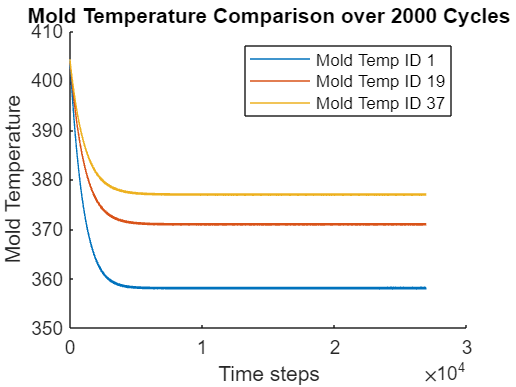


% Generate timestamps for plotting
timestamps = (0.0:t_step:(length(gob_ts_all{1})-1)*t_step);

% Create a separate figure for Mold Temperatures
figure(1); clf;  % Clear any existing data in figure 2
hold on;
for idx = 1:num_ids
    plot(timestamps, mold_ts_all{idx}, 'DisplayName', ['Mold Temp ID ', num2str(ids(idx))]);
end
xlabel('Time steps');
ylabel('Mold Temperature');
title('Mold Temperature Comparison over 2000 Cycles');
legend show;
hold off;

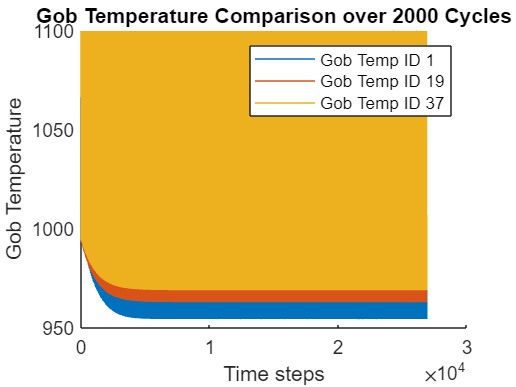



% Create a separate figure for Gob Temperatures
figure(2); clf;  % Clear any existing data in figure 1
hold on;
for idx = 1:num_ids
    plot(timestamps, gob_ts_all{idx}, 'DisplayName', ['Gob Temp ID ', num2str(ids(idx))]);
end
xlabel('Time steps');
ylabel('Gob Temperature');
title('Gob Temperature Comparison over 2000 Cycles');
legend show;
hold off;




% Function to simulate a cycle

function [gob_ts, mold_ts, gob_hfs, cool_hfs] = simulate_cycle(T_gob_initial, T_mold_initial, ...
    t_settle_start, t_settle_duration, t_counter_start, t_counter_duration, ...
    t_cooling_start, t_cooling_duration, cycle_end, t_step, a1, a2, b1, b2, ks, kc, ...
    S_settle, S_counter, S_aria, C_mold, C_gob, T_air)

    % Initialize temperatures and times
    T_gob = T_gob_initial;
    T_mold = T_mold_initial;
    time = 0.0;

    gob_ts = T_gob_initial;  % Start with the initial temperature
    mold_ts = T_mold_initial;
    gob_hfs = 0.0;
    cool_hfs = 0.0;

    % Loop over the cycle time
    while time < cycle_end
        hf_gob = 0.0;
        hf_cool = 0.0;

        if time >= t_settle_start && time < t_settle_start + t_settle_duration
            [T_gob, T_mold, hf_gob] = simulate_settle(a1, a2, ks, T_gob, T_mold, t_step, S_settle, C_mold, C_gob);
        end

        if time >= t_counter_start && time < t_counter_start + t_counter_duration
            [T_gob, T_mold, hf_gob] = simulate_counter(b1, b2, kc, T_gob, T_mold, t_step, S_counter, C_mold, C_gob);
        end

        if time >= t_cooling_start && time < t_cooling_start + t_cooling_duration
            [T_mold, hf_cool] = simulate_cooling(T_mold, t_step, S_aria, T_air, C_mold);
        end

        if time >= t_counter_start + t_counter_duration && time < cycle_end
            T_mold = simulate_passive_cooling(T_mold, t_step, T_air, C_mold);
        end

        % Append the scalar values to the arrays
        gob_ts(end+1) = T_gob;  % Append scalar T_gob to gob_ts array
        mold_ts(end+1) = T_mold; % Append scalar T_mold to mold_ts array
        gob_hfs(end+1) = hf_gob; % Append scalar heat flow from gob to gob_hfs array
        cool_hfs(end+1) = hf_cool; % Append scalar cooling heat flow to cool_hfs array

        % Increment time
        time = time + t_step;
    end
end

% Simulate settle phase
function [T_g_s, T_m_s, hf_settle] = simulate_settle(a1, a2, ks, T_g, T_m, t_step, S_settle, C_mold, C_gob)
    T_g_surface = polyval(a2, T_g - T_m); % Evaluate polynomial for T_g_surface
    T_m_surface = polyval(a1, T_g - T_m); % Evaluate polynomial for T_m_surface
    
    hf_settle = S_settle * polyval(ks, T_g_surface - T_m_surface); % Heat flow during settle
    
    T_m_s = T_m - (hf_settle * C_mold * t_step); % Update mold temperature
    T_g_s = T_g + (hf_settle * C_gob  * t_step); % Update gob temperature
end

% Simulate counter phase
function [T_g_c, T_m_c, hf_counter] = simulate_counter(b1, b2, kc, T_g, T_m, t_step, S_counter, C_mold, C_gob)
    T_g_surface = polyval(b2, T_g - T_m); % Evaluate polynomial for T_g_surface
    T_m_surface = polyval(b1, T_g - T_m); % Evaluate polynomial for T_m_surface
    
    hf_counter = S_counter * polyval(kc, T_g_surface - T_m_surface); % Heat flow during counter
    
    T_m_c = T_m - (hf_counter * C_mold * t_step); % Update mold temperature
    T_g_c = T_g + (hf_counter * C_gob  * t_step); % Update gob temperature
end

% Simulate cooling phase
function [T_m_c, hf_cooling] = simulate_cooling(T_m, t_step, S_aria, T_air, C_mold)
    hf_cooling = S_aria * 360 * (T_air - T_m); % Cooling heat flow
    T_m_c = T_m + (hf_cooling * C_mold * t_step); % Update mold temperature
end

% Simulate passive cooling phase
function [T_m_c] = simulate_passive_cooling(T_m, t_step, T_air, C_mold)
    hf_passive = (T_m - T_air) * 1.053 - 40.99; % Passive cooling heat flow
    T_m_c = T_m - (hf_passive * C_mold * t_step); % Update mold temperature
end

